# Working with Outliers 

## Introduction

Not arriving at your destination when planned is a major source of frustration in air travel. With the exception of things like cancellations and diversions, the total arrival delay has two main components: the difference between actual and scheduled gate-to-gate time, and the delay in departing to begin with. To put this in terms of the table variables, 

`ARRIVAL_DELAY = DEPARTURE_DELAY + ( ACTUAL_ELAPSED_TIME - SCHEDULED_ELAPSED_TIME )` 

Below, you'll investigate both components of arrival delay. You'll see how outliers affect their visualization and analysis. Then you'll apply and compare various methods and thresholds to identify and/or remove outliers. 

Next, you'll investigate another source of frustration in air travel: flight cancellations. You'll see how to use the methods you've learned to identify outliers in data as a way to find and extract unusual data for further analysis: in this case a particularly high cancellation rate surrounding a severe winter weather. You'll then be able to use the same techniques to search for your own exceptional data. 

Finally, you'll take a look at how quick or slow air travel can be overall by computing the average velocity between origin and destination gates for all flights in your data: 

`AVE_VELOCITY = DISTANCE/ACTUAL_ELAPSED_TIME`

You'll see how to analyze this quantity as a function of distance, and how to use moving identification and removal methods to more effectively work with outliers in such scenarios. 

To start, choose and import the flights and airport data you want to work with. 

## Import and Merge Flights and Airport Data

This section imports flights data for the month of January and the airports data for use below. If you would like to analyze more than one month at a time, remember you can use a datastore as you have seen previously to import the entire year, then extract any portion of it you want. Also you can use the joining operations you learned to add information from the airports table to the flights table. 

% import the flights data for January 
flights = importFlightsData("flightsJan.csv");

airports = readtable("airports.csv","TextType","String");
airports.AIRPORT = categorical(airports.AIRPORT); 
airports.CITY_STATE = split(airports.DISPLAY_AIRPORT_CITY_NAME_FULL,", ");
airports = splitvars(airports,"CITY_STATE","NewVariableNames",["CITY" , "STATE"]);
airports = removevars(airports,"DISPLAY_AIRPORT_CITY_NAME_FULL");
airports.Properties.VariableNames("DISPLAY_AIRPORT_NAME") = "AIRPORT_NAME";

## Actual vs. Scheduled Elapsed Time 

To start investigating how much and how often flights arrive late, first take a look at the difference in actual and scheduled elapsed time. 

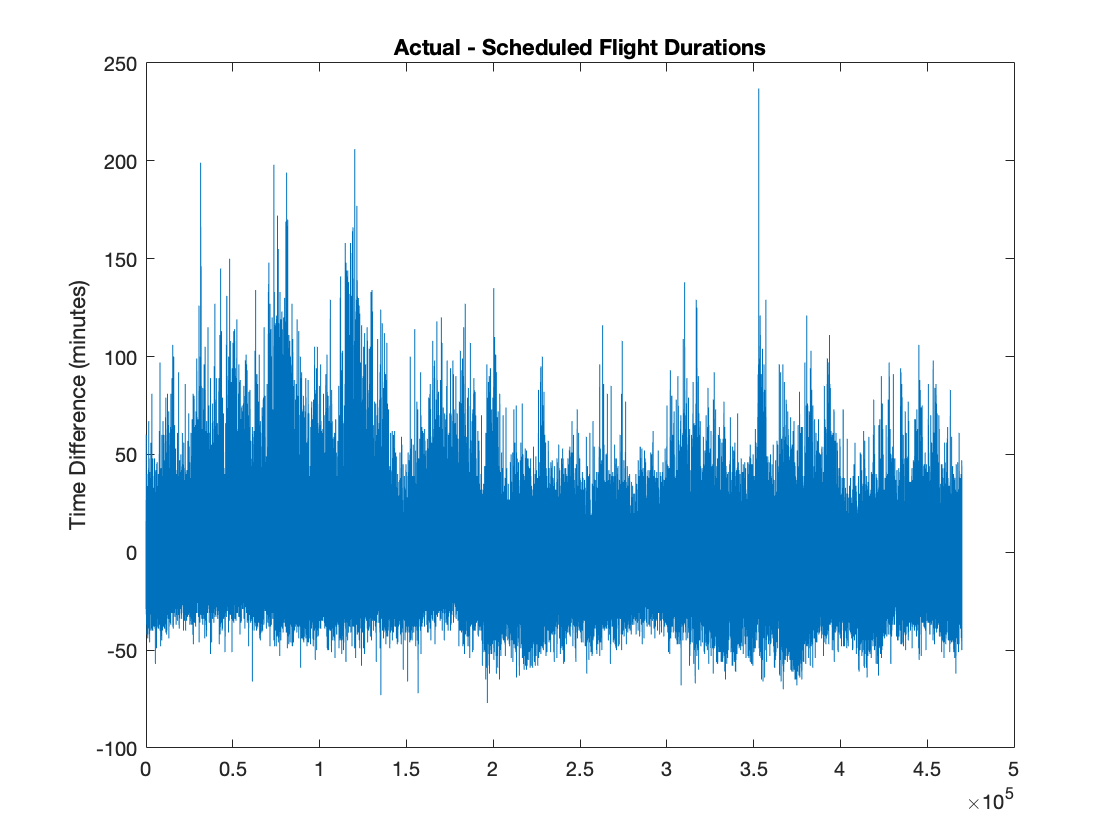

% calculate the difference between actual and scheduled elapsed flight times
dElapsed = flights.ACTUAL_ELAPSED_TIME - flights.SCHEDULED_ELAPSED_TIME;


% plot the result 

plot(dElapsed); 
title("Actual - Scheduled Flight Durations");
ylabel("Time Difference (minutes)"); 

Plotting a very large amount of data like a signal often does not make it easy to really see how the data is distributed due to the density of the plot. 

### Evaluate the distribution using a histogram instead of a plot

A histogram will provide a better way to view the distribution of time differences. Enter the number of bins to use. 

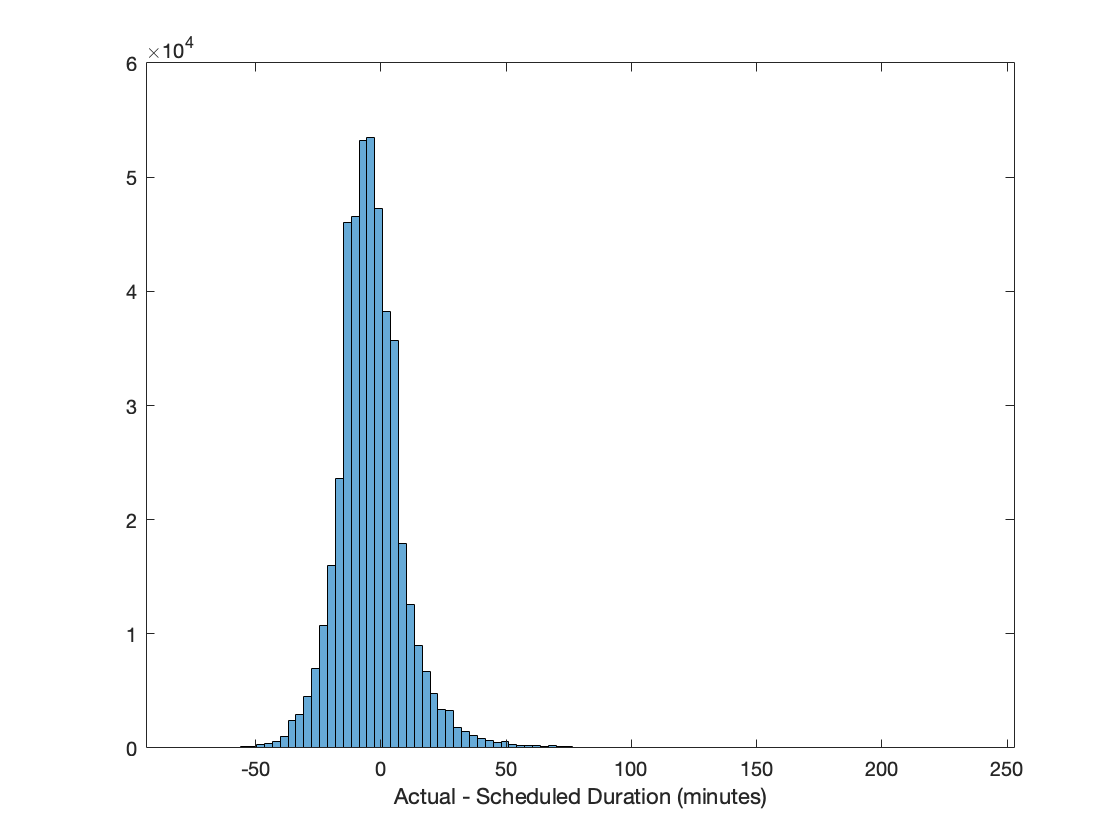

nBins_dElapsed = 100;

histogram(dElapsed,nBins_dElapsed); 
xlabel("Actual - Scheduled Duration (minutes)"); 

### Re-visualize after using three common methods of removing outliers

Even though using a histogram can give you a better picture of the data distribution, large outliers can still bias the scaling and reduce the amount of detail you can see with respect to the bulk of the data. Removing or ignoring large outliers can aid visualization.  

There are three common methods used for classifying and removing outliers:

- median – median absolute deviations above/below median\

- mean – standard deviations above/below mean

- quartiles –interquartile range above/below the third/first quartiles.

Use the dropdown control below to select which method you want to apply. 

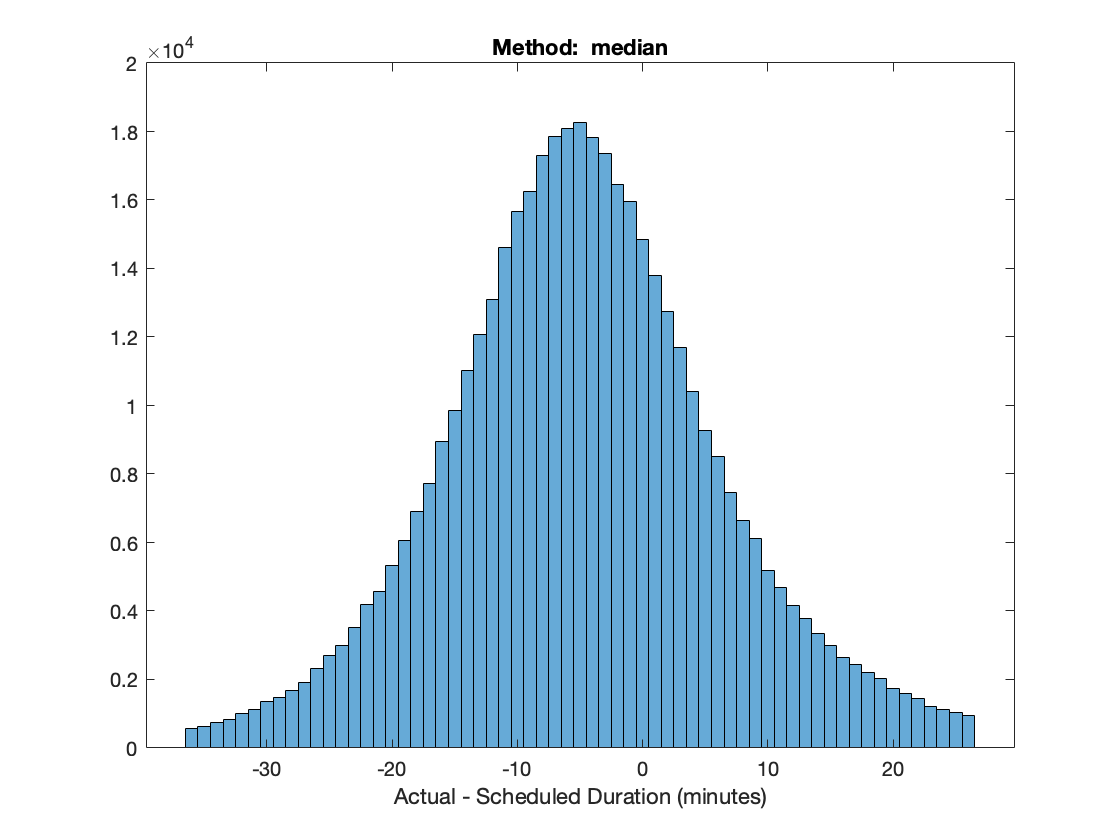

outMethod = "median"; % method to classify outliers 
% Use the choice above to speicfy the methood used in rmoutliers
dElapsedTrimmed = rmoutliers(dElapsed,outMethod); 


histogram(dElapsedTrimmed,"BinMethod","Integers"); 
xlabel("Actual - Scheduled Duration (minutes)");
title("Method:  " + outMethod)

### Adjust the amount removed using the threshold factor setting

Sometimes you are not happy with the default amount removed by any of the three methods above. Try adjusting the cutoff bounds by specifying the threshold factor parameter. 

Use the slider control to set a threshold factor. (You can verify using the [documentation](https://www.mathworks.com/help/matlab/ref/rmoutliers.html) for `rmoutliers` the default is 3 for the mean and median methods, and 1.5 for quartiles.)

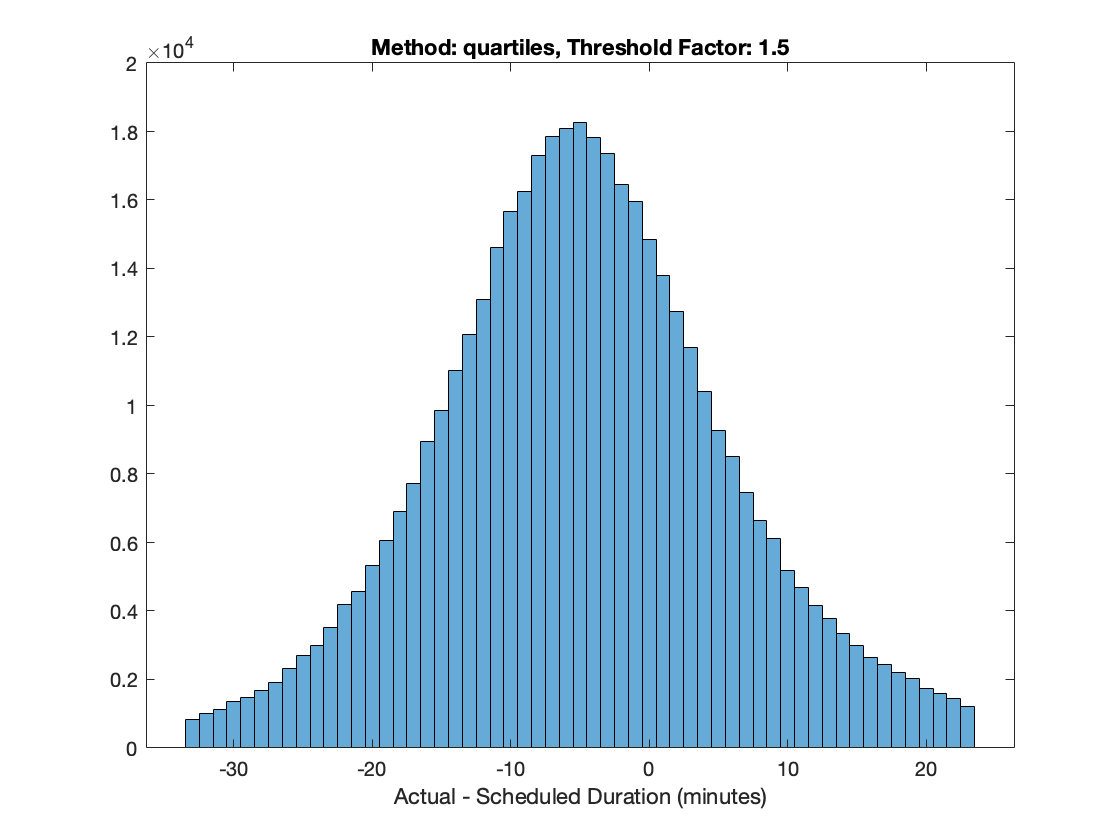

outMethod = "quartiles"; % method to classify outliers 
tFactor = 1.5; % threshold factor to classify outliers 

% Use choices above to specify the method and threshold factor used in rmoutliers
dElapsedTrimmed = rmoutliers(dElapsed,outMethod,"ThresholdFactor",tFactor); 


histogram(dElapsedTrimmed,"BinMethod","Integers");
xlabel("Actual - Scheduled Duration (minutes)"); 
title("Method: " + outMethod + ", Threshold Factor: " + tFactor);

### Visualize mean+/-std thresholds on the distribution

Visualizing where the bounds will be on the distribution before removing anything is often a good idea. One approach is to add the thresholds on the distribution itself as vertical lines. You can even label them. 

Adjust the threshold factor below to observe the bounds move on the distribution. The vertical lines and optional labels are added using the `xline` command. 

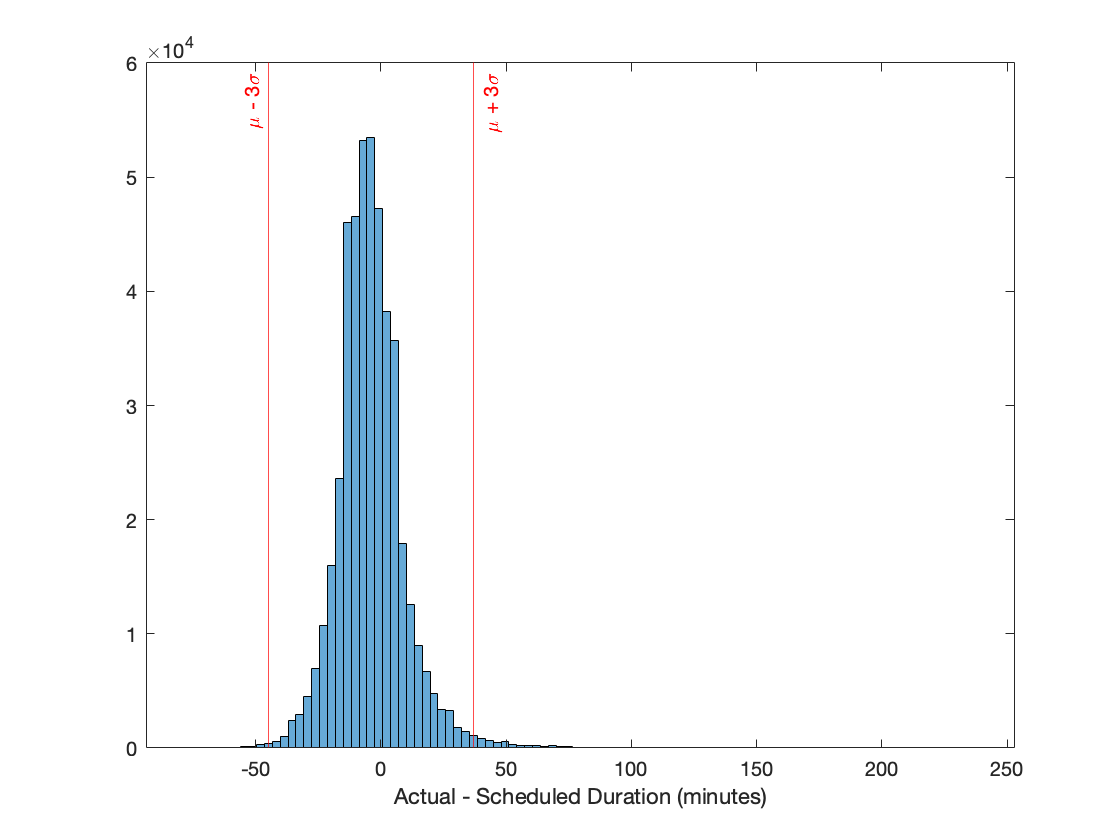

tFactor = 3; % threshold factor to classify outliers 
[TF,L,U,C] = isoutlier(dElapsed,"mean","ThresholdFactor",tFactor); 


histogram(dElapsed,100); 
xlabel("Actual - Scheduled Duration (minutes)");
% add the thresholds from isoutlier to the distribution and add labels 
xline(L,"r","\mu - " + string(tFactor) +"\sigma","LabelHorizontalAlignment","left");
xline(U,"r","\mu + " + string(tFactor) +"\sigma"); 

## Departure Delays

To continue investigating late arrivals, look at the other major component: departure delays.  

This time start with a histogram to get an idea of the distribution. 

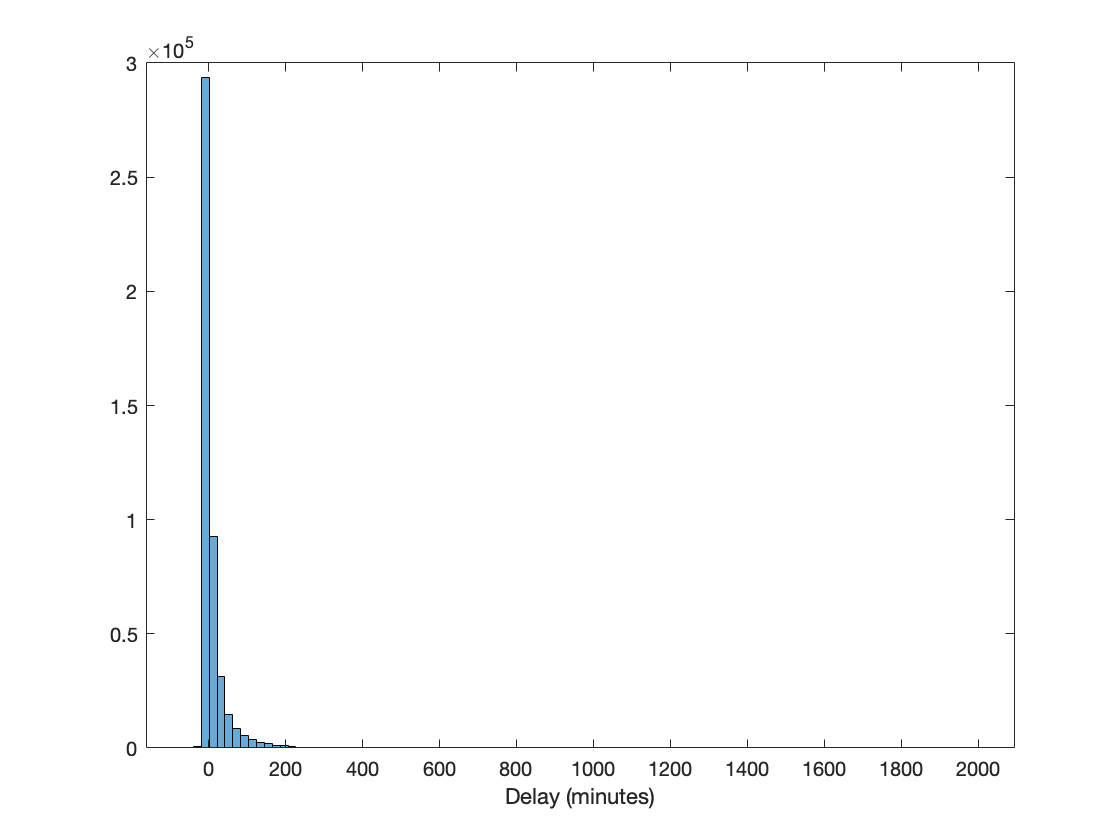


histogram(flights.DEPARTURE_DELAY,100); 
xlabel("Delay (minutes)"); 

While the data you are interested lies between 0 and 200, there are outliers as far out as 2000. In order to fit all the data in the figure, the information you are actually interested in seeing is getting compressed to the left side.

### Trim outliers using the default common methods to improve the visualization 

Again, you can get a more detailed view of the bulk of the distribution by using any of the popular methods of outlier removal on the data before visualizing it. 

Use the dropdown control below to select which of the three common methods of classifying outliers you want to use to try and get a better picture of the main part of the distribution. 

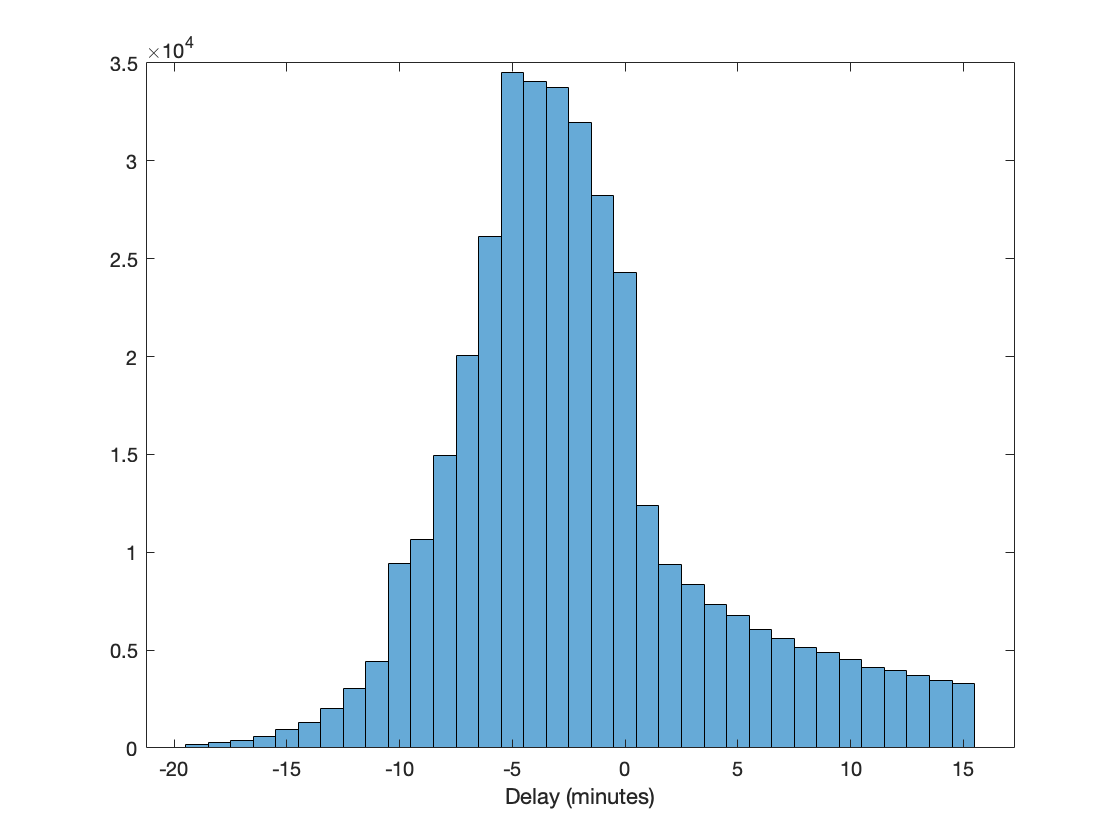

depDelayTrimmed = rmoutliers(flights.DEPARTURE_DELAY,"median"); 


histogram(depDelayTrimmed);  
xlabel("Delay (minutes)"); 

### Visualize and compare the outlier thresholds for each method together with the data distribution

To compare the bounds for multiple outlier classification methods at once on the distribution, just add each as a new pair of vertical lines again using `xline`. You may also want to try adding labels to each as done previously to further differentiate them. Alternatively, you could try adding a legend to the plot. If you try the legend approach, you may want to look into the [documentation](https://www.mathworks.com/help/matlab/ref/legend.html#bt6ef_q-1-subset) for labeling only a subset of the graphics objects. 

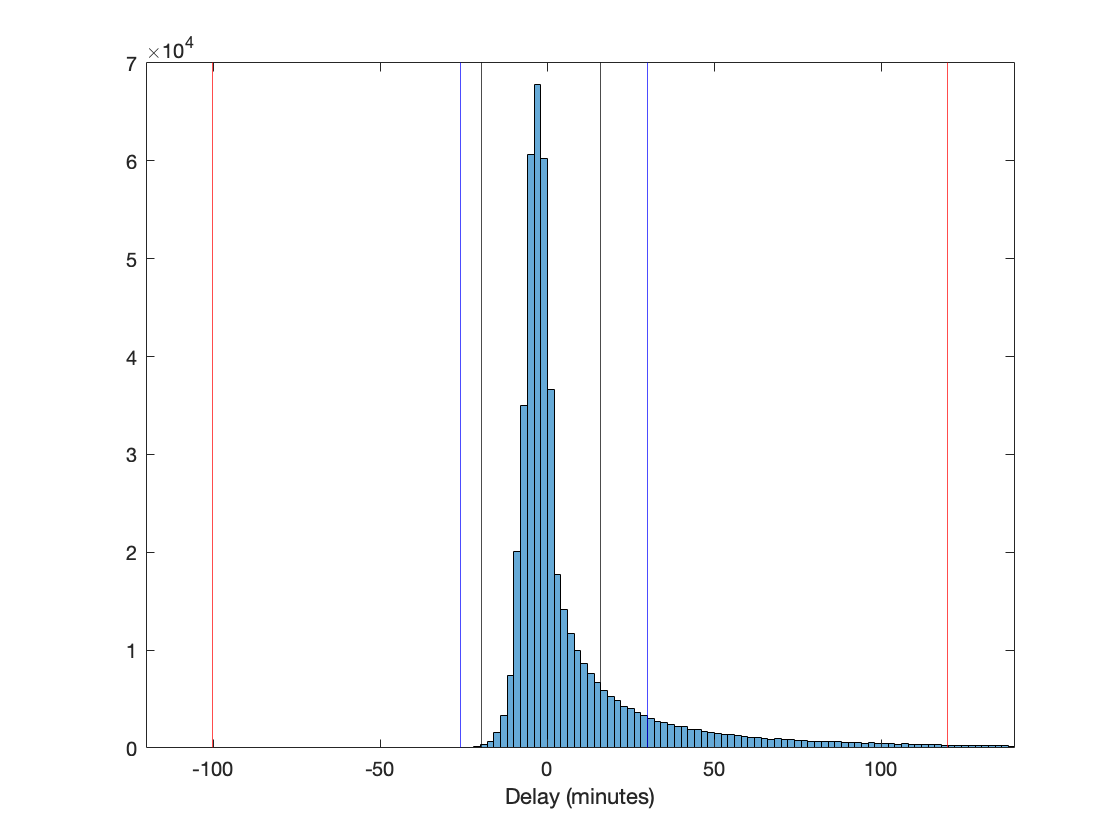


[~,stdLow,stdHigh,~] = isoutlier(flights.DEPARTURE_DELAY,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(flights.DEPARTURE_DELAY,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(flights.DEPARTURE_DELAY,"median");  


histogram(flights.DEPARTURE_DELAY);  
xlabel("Delay (minutes)"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k"); 


xlim([stdLow-20,stdHigh+20]) % optional zooom in to better see bounds 

Note that each of the three common methods of outlier classification you've been using up to this point are symmetric above and below their respective centers. In other words, if you adjust the scaling via threshold factor to include more of the data in the positive direction, you'll necessarily expand the negative bound by the same amount. With data that is heavily skewed like departure delays, this means you'll include some potentially empty space in one direction. 

### Use percentile thresholds to have flexibility with extremely skewed data 

There are methods you can use which allow you to adjust or skew the bounds in one direction or another as you see fit. One way to do this is setting percentile bounds, i.e. by choosing bounds based on a number of intervals containing 1% of the data from low to high. 

Set a low and high percentile threshold below. 

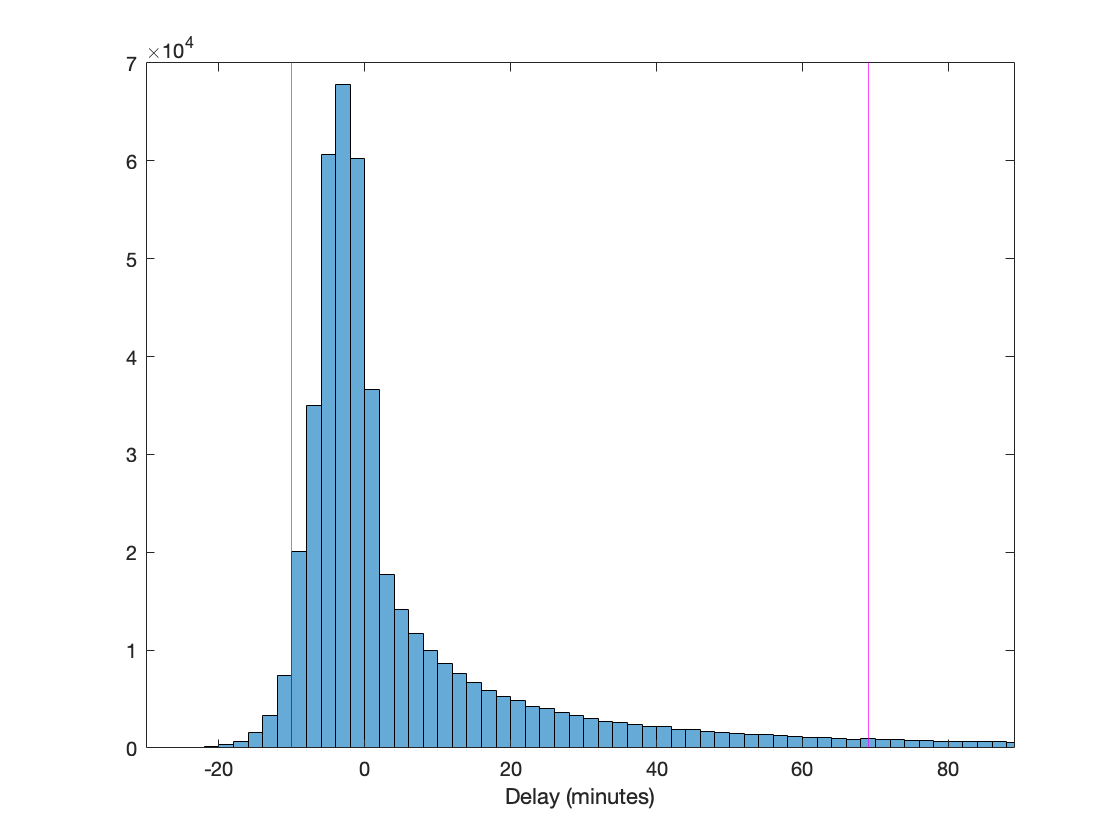

lowPercent = 5; 
highPercent = 95; 

% use the above choices with the percentile outlier classification method
[~,pLow,pHigh,~] = isoutlier(flights.DEPARTURE_DELAY,...
    "percentiles",[ lowPercent , highPercent ]);  


histogram(flights.DEPARTURE_DELAY);  
xlabel("Delay (minutes)"); 
xline(pLow,"m"); xline(pHigh,"m"); 

xlim([pLow - 20 , pHigh + 20]) % optional zooom in to better see bounds 

Try modifying this script to add the percentile bounds to the same figure as the other methods, and see how the bounds of each can be adjusted.

Besides identification and/or removal, outliers may need further investigation. For example, departure delays longer than a day (1440 minutes). 

longDepDelays = flights.DEPARTURE_DELAY(flights.DEPARTURE_DELAY >= 1440)

longDepDelays =         1450
        1604
        1457
        1988
        1551


If you take a look inside the data import function provided to you, `importFlightsData.mlx`, you will see that flights with delays longer than the 1440 minutes in a day did require some special attention due to the original data only having one date corresponding to the scheduled departure time. Using the recorded date for the arrival of these flights would have been incorrect. 

## Cancellation Rate Outliers 

Often, cancellations are due to factors such as weather events. To investigate flight cancellations, you can start by using `groupsummary` to calculate the total number of flights cancelled each day in the data. 

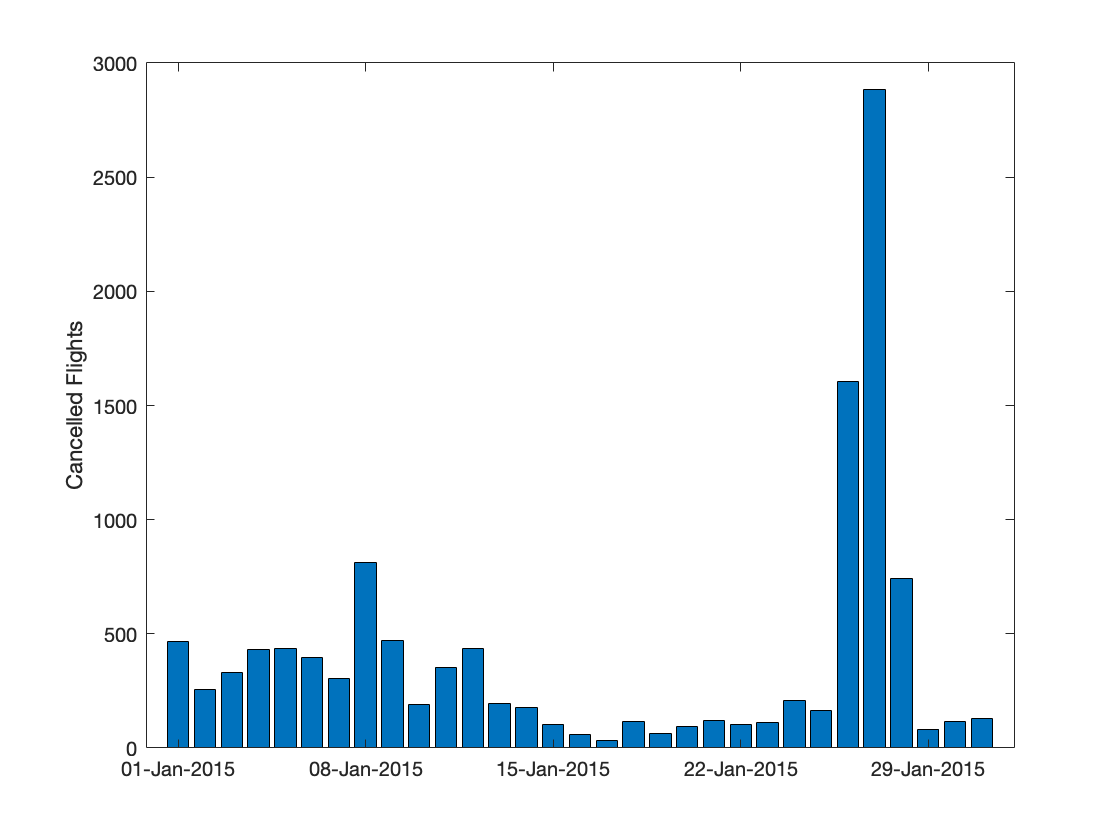

cancelledPerDay = groupsummary(flights,"SCHEDULED_DEPARTURE_TIME",...
    "day","sum","CANCELLED");
% convert the categorical bins to datetime data type and visualize the result 

bar(datetime(string(cancelledPerDay.day_SCHEDULED_DEPARTURE_TIME)), ...
    cancelledPerDay.sum_CANCELLED); 
ylabel("Cancelled Flights"); 

### Choose a specific date to examine further and visualize geographically

After examining the bar plot of cancellations per day, choose a date below to investigate further. (Make sure the date is in your data!) 


canDayOfMonth = "27 ";

% use the above choice to extract the cancelled flights on that date
canDate = datetime("2015-Jan-" + canDayOfMonth);
canDateIdx = day(flights.SCHEDULED_DEPARTURE_TIME,"dayofyear") == day(canDate,"dayofyear");
canFlights = flights( canDateIdx & flights.CANCELLED == 1,:); 

% extract the destinations with the top 10 most cancelled flights 
topCanDest = topkrows(groupsummary(canFlights,"DESTINATION"),10,"GroupCount","Descend");
topCanDest = innerjoin(airports,topCanDest,"RightKeys","DESTINATION", ...
    "LeftKeys","AIRPORT","LeftVariables",["AIRPORT","LATITUDE","LONGITUDE"]);
topCanDest.Properties.VariableNames("GroupCount") = "DESTINATION_CANCELLATIONS"

topCanDest = 10×4 table
    AIRPORT    LATITUDE    LONGITUDE    DESTINATION_CANCELLATIONS
    _______    ________    _________    _________________________

      ATL       33.641      -84.427                 94           
      BOS       42.364      -71.006                301           
      EWR       40.696      -74.172                272           
      FLL       26.074      -80.152                 67           
      JFK       40.639      -73.777                206           
      LAX       33.943      -118.41                 74           
      LGA       40.779      -73.876                311           
      MCO       28.432      -81.325                 86           
      ORD       41.978      -87.906                107           
      PHL       39.868      -75.249                125           



% extract the origins with the top 10 most cancelled flights 
topCanOrigins = topkrows(groupsummary(canFlights,"ORIGIN"),10,"GroupCount","Descend");
topCanOrigins = innerjoin(airports,topCanOrigins,"RightKeys","ORIGIN", ... 
    "LeftKeys","AIRPORT","LeftVariables",["AIRPORT","LATITUDE","LONGITUDE"]);
topCanOrigins.Properties.VariableNames("GroupCount") = "ORIGIN_CANCELLATIONS"

topCanOrigins = 10×4 table
    AIRPORT    LATITUDE    LONGITUDE    ORIGIN_CANCELLATIONS
    _______    ________    _________    ____________________

      ATL       33.641      -84.427              79         
      BOS       42.364      -71.006             306         
      DCA       38.852      -77.037              68         
      EWR       40.696      -74.172             293         
      FLL       26.074      -80.152              59         
      JFK       40.639      -73.777             251         
      LGA       40.779      -73.876             332         
      MCO       28.432      -81.325              73         
      ORD       41.978      -87.906              95         
      PHL       39.868      -75.249             161         



% combine the destinations and origins appearing on both top 10 lists
topCanAirports = innerjoin(topCanDest,topCanOrigins);
topCanAirports.AIRPORT = removecats(topCanAirports.AIRPORT); 
topCanAirports.TOTAL_CANCELLATIONS = topCanAirports.DESTINATION_CANCELLATIONS ...
    + topCanAirports.ORIGIN_CANCELLATIONS;
topCanAirports = sortrows(topCanAirports,"TOTAL_CANCELLATIONS","descend")

topCanAirports = 9×6 table
    AIRPORT    LATITUDE    LONGITUDE    DESTINATION_CANCELLATIONS    ORIGIN_CANCELLATIONS    TOTAL_CANCELLATIONS
    _______    ________    _________    _________________________    ____________________    ___________________

      LGA       40.779      -73.876                311                       332                     643        
      BOS       42.364      -71.006                301                       306                     607        
      EWR       40.696      -74.172                272                       293                     565        
      JFK       40.639      -73.777                206                       251                     457        
      PHL       39.868      -75.249                125                       161          

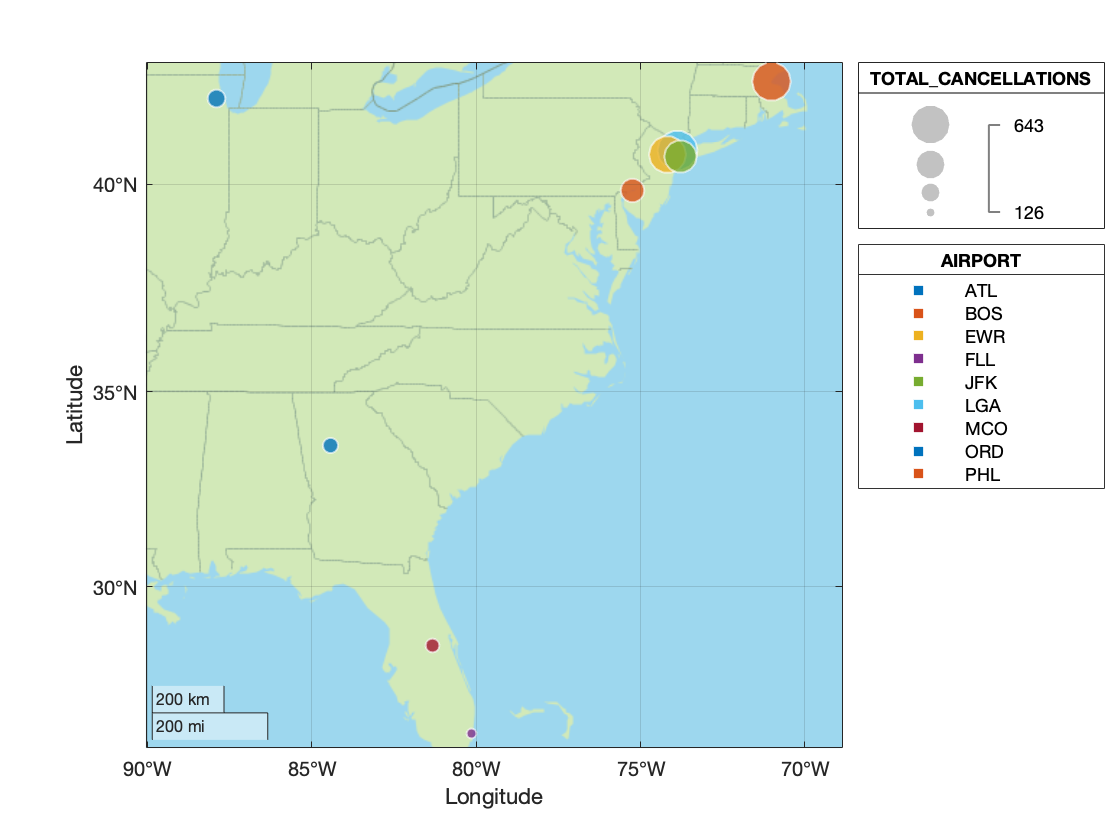

geobubble(topCanAirports,"LATITUDE","LONGITUDE","Basemap","bluegreen", ...
     "SizeVariable","TOTAL_CANCELLATIONS","ColorVariable","AIRPORT");

If you've chosen January 27th, you'll see that most of the cancellations occurred in airports in the Northeast portion of the US. 

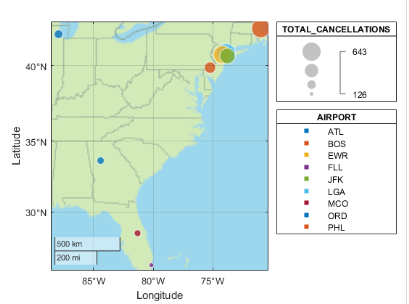

Searching online, you will find that at the same time there was a major blizzard in this region: 

[https://www.weather.gov/okx/Blizzard_01262715](https://www.weather.gov/okx/Blizzard_01262715)

Try to find other unusually high rates of cancellation throughout the year, and think about if you can connect likely causes based on the time and geography, or other factors you determine. 

## Average Gate-to-Gate Velocity 

Assuming the flight departs the origin gate, how fast or slow is air travel overall? Calculate the average velocity ( displacement / time ) of each flight using the `DISTANCE` and `ACTUAL_ELAPSED_TIME` variables.   

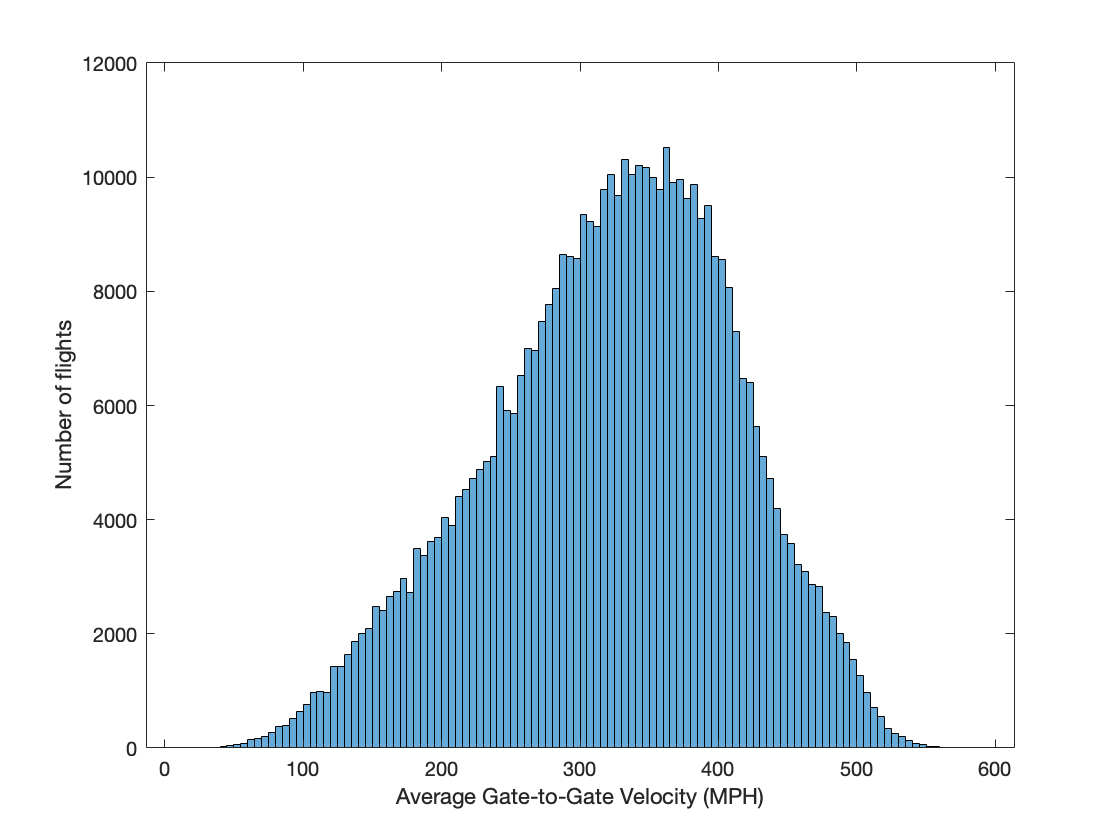

% calculate the average gate-to-gate velocities in miles-per-hour
flights.AVE_VELOCITY = 60*flights.DISTANCE./flights.ACTUAL_ELAPSED_TIME; 


histogram(flights.AVE_VELOCITY); 
xlabel("Average Gate-to-Gate Velocity (MPH)"); 
ylabel("Number of flights"); 

### Visualize average velocity as function of distance 

It looks like the average velocities are most commonly between 3 and 400 miles-per-hour. However some of the flights seem surprisingly slow, even below typical highway speeds. Before removing anything as outliers, consider that this distribution may be a function of some other variable like distance. 

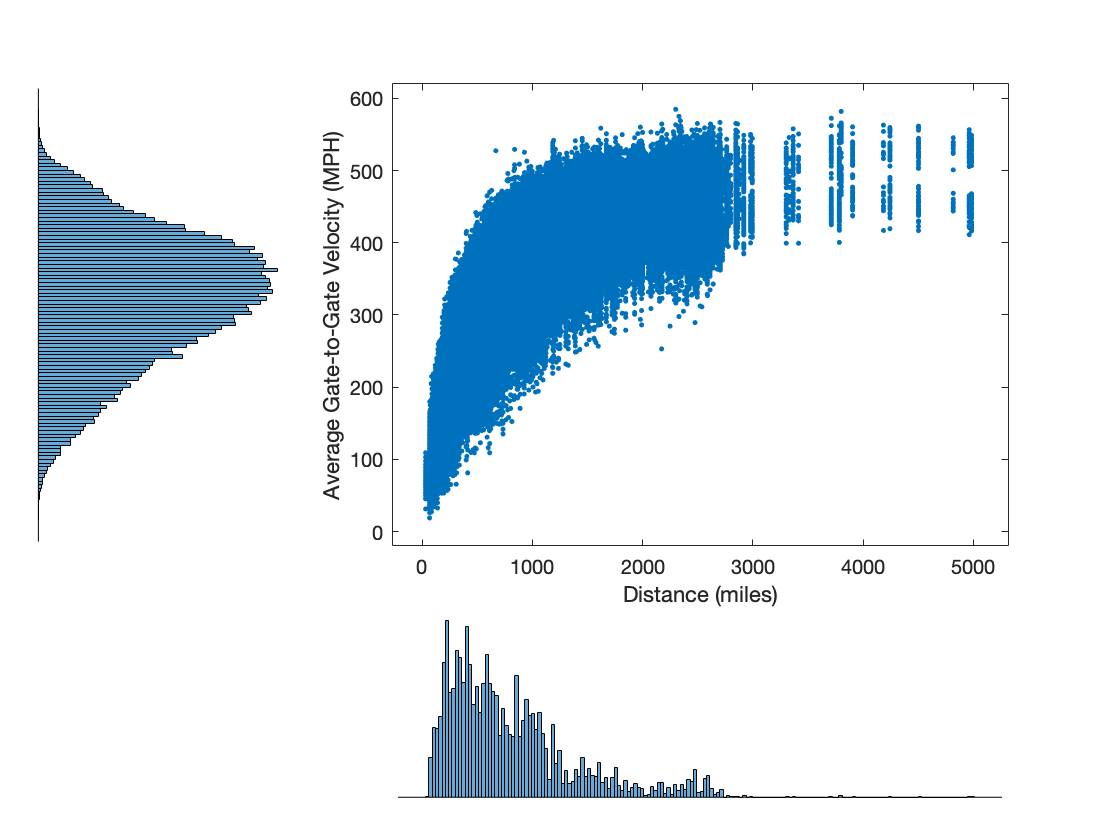


scatterhist(flights.DISTANCE,flights.AVE_VELOCITY,"Marker","."); 
xlabel("Distance (miles)"); 
ylabel("Average Gate-to-Gate Velocity (MPH)")

Plotting average velocities as a function of distance confirms there is a relationship between average velocity and total distance, so defining outliers based on the distribution of velocity alone is not ideal. To make things more difficult there is a distribution of multiple data points at each velocity, meaning we cannot directly apply moving average or median methods since they require one data point at each index. To get around this, one approach is to calculate some summary statistics for the distribution at each distance. 

### Calculate summary statistics for the average velocity distribution at each distance 

If you calculate summary statistics at every distance, you'll get a one-value-per-distance "signal" that you can use moving outlier classification / removal methods on. 

flights = sortrows(flights,"DISTANCE"); 
velStats = groupsummary(flights,"DISTANCE",["max","min","mean","median"],"AVE_VELOCITY");

### Find outliers in the maximum average velocity at each distance

In order to use either moving average (mean) or median you will need to decide on a window length, i.e. the number of consecutive data points used to calculate the moving statistic. Although optional, you can specify additional parameters like threshold factor similar to how you would with the non-moving methods. Try out the different methods, window lengths, and threshold factors below to see how they affect the bounds in the subsequent visualization. 

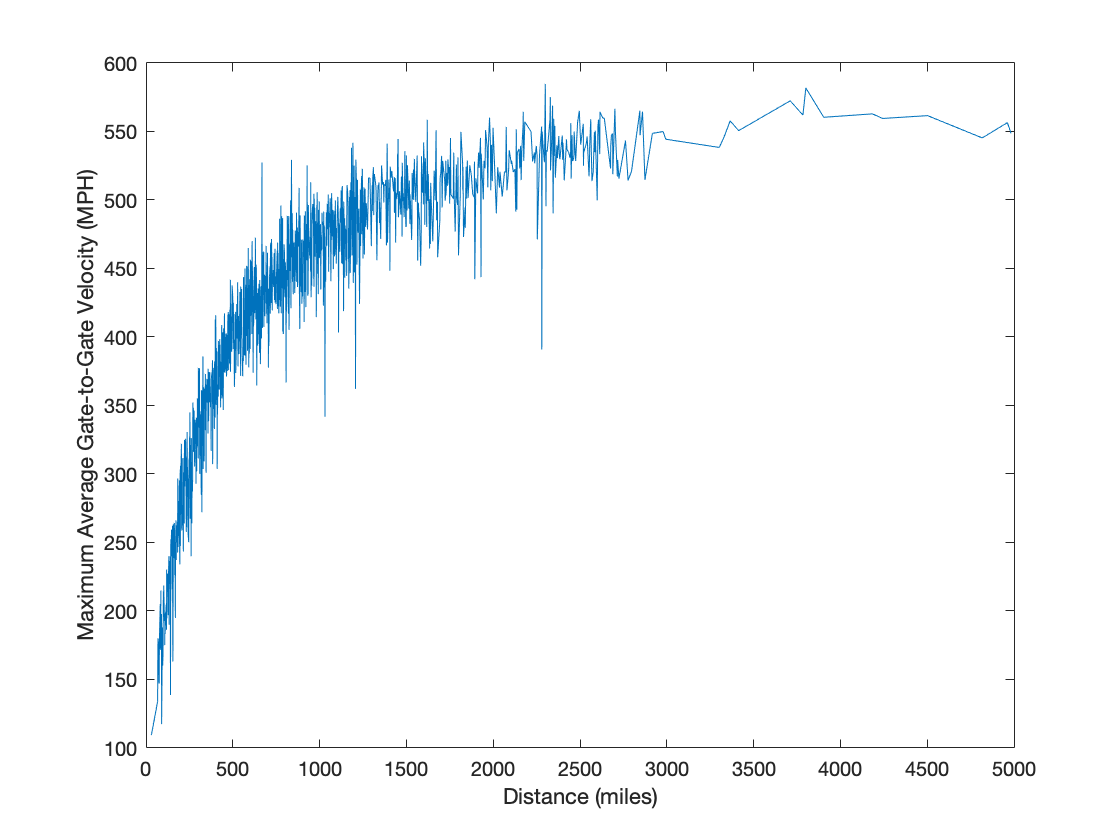

% figure;
plot(velStats.DISTANCE,velStats.max_AVE_VELOCITY); 
xlabel("Distance (miles)"); 
ylabel("Maximum Average Gate-to-Gate Velocity (MPH)")

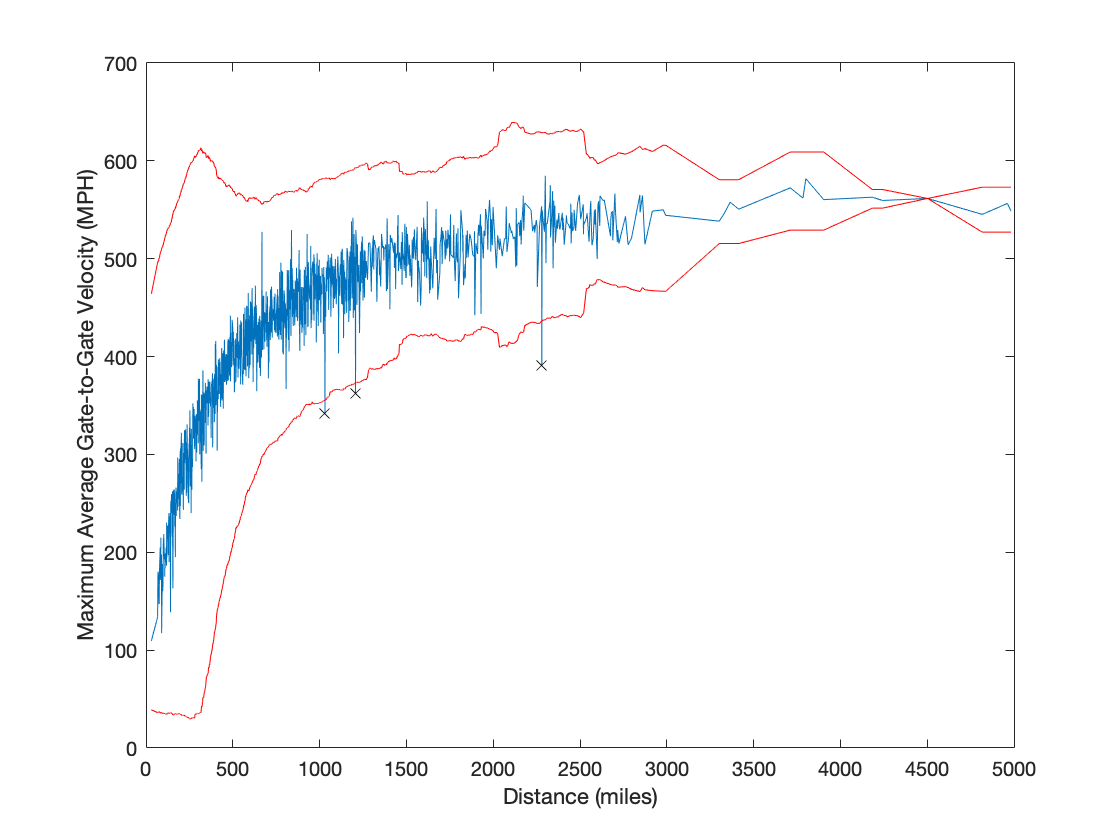


% Find outliers
moveMethod = "movmean"; 
windowLength = 500; 
tFactor = 4; 

[outlierIdx,thresholdLow,thresholdHigh] =  isoutlier(velStats.max_AVE_VELOCITY, ...
    moveMethod,windowLength,"ThresholdFactor",tFactor,"SamplePoints",velStats.DISTANCE);


plot(velStats.DISTANCE,velStats.max_AVE_VELOCITY); 
xlabel("Distance (miles)"); 
ylabel("Maximum Average Gate-to-Gate Velocity (MPH)")
hold on
plot(velStats.DISTANCE(outlierIdx),velStats.max_AVE_VELOCITY(outlierIdx),"kx")
plot(velStats.DISTANCE,thresholdLow,"r"); 
plot(velStats.DISTANCE,thresholdHigh,"r"); 
hold off

### Remove the median and identify outliers at each distance

To remove outliers from the average gate-to-gate velocity as a whole, you'll need to do something to essentially isolate the deviation around a center. Since you've already calculated the median at each distance, an easy way to accomplish this is to simply subtract the median to "center" the distribution of velocities at each distance. 

flightsVelocities = innerjoin(flights,velStats,"Keys","DISTANCE", ...
    "LeftVariables",[ "AVE_VELOCITY" "DISTANCE"]);
% subtract the median at each distance to center the distributions
velDeviation = flightsVelocities.AVE_VELOCITY - flightsVelocities.median_AVE_VELOCITY; 


scatterhist(flightsVelocities.DISTANCE,velDeviation,"NBins",100,"Marker","."); 
xlabel("Distance (miles)"); 
ylabel("Average Gate-to-Gate Velocity (MPH)"); 
hold on; 

Now you can use any of the non-moving methods to more meaningfully classify and/or remove outliers, e.g. percentiles. 

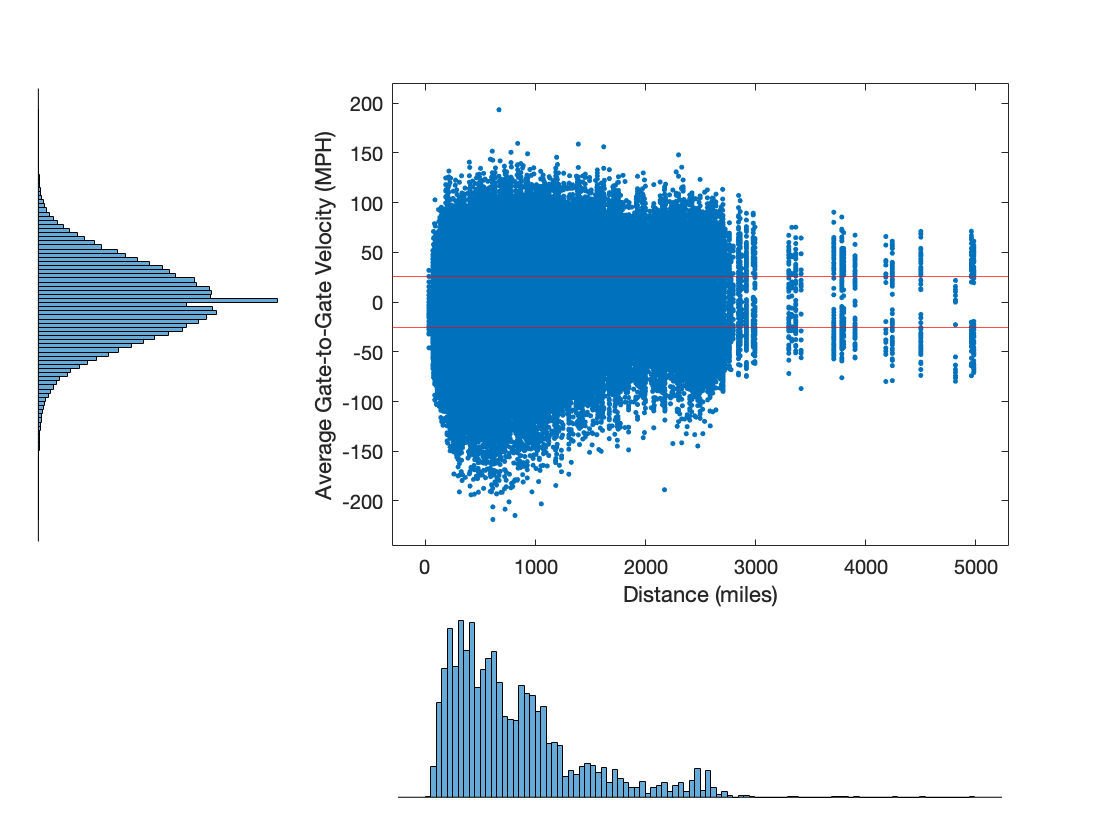

lowPercent = 25; 
highPercent = 75; 

% use the above choices with the percentile outlier classification method

[vOut,vLow,vHigh,~] = isoutlier(velDeviation,"percentiles",[ lowPercent , highPercent ]); 
yline(vLow,"r"); 
yline(vHigh,"r"); 
hold off; 

Give some of the other methods a try on your own. The outputs from `isoutlier` should not need to change to use different detection settings. 

The output `vOut` from `isoutlier` is a logical vector which is true at indices where outliers were identified and false where they were not. You can use this to extract the portion of the data not considered to be outliers by negating these logical values and using the result to index into the data. 

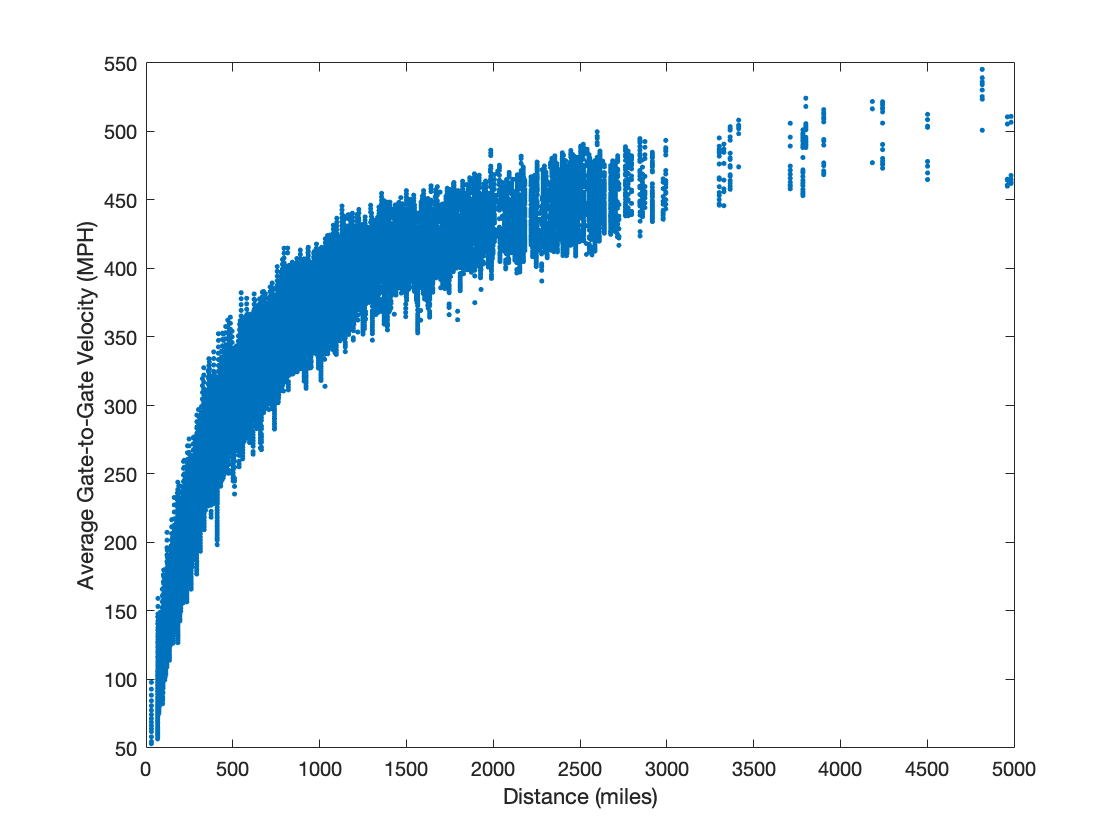


plot(flightsVelocities.DISTANCE(~vOut),flightsVelocities.AVE_VELOCITY(~vOut),"."); 
xlabel("Distance (miles)"); ylabel("Average Gate-to-Gate Velocity (MPH)");

You can also visualize how the bounds look on the original data by adding the median at each distance to the `vLow` and `vHigh` values. Give this a try below. 

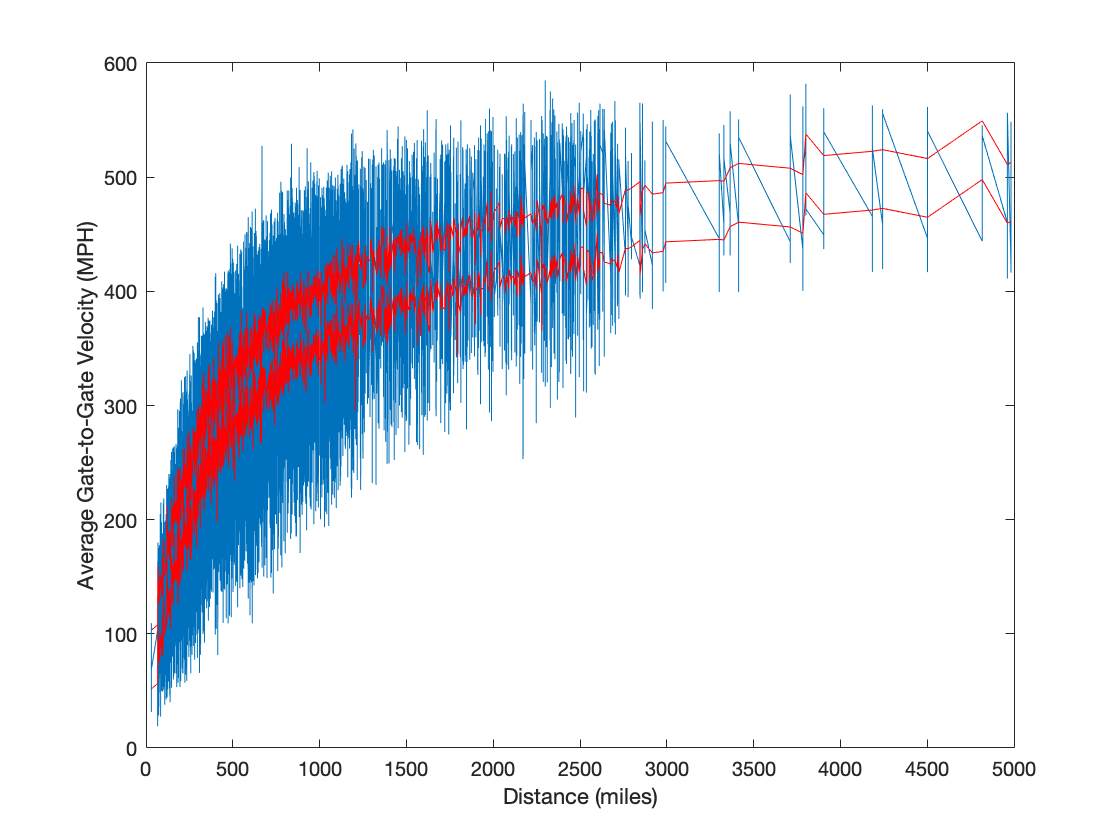

oLow = vLow + flightsVelocities.median_AVE_VELOCITY;
oHigh = vHigh + flightsVelocities.median_AVE_VELOCITY;

plot(flightsVelocities.DISTANCE,flightsVelocities.AVE_VELOCITY); 
xlabel("Distance (miles)"); 
ylabel("Average Gate-to-Gate Velocity (MPH)"); 
hold on; 

plot(flightsVelocities.DISTANCE,oLow,"r"); 
plot(flightsVelocities.DISTANCE,oHigh,"r"); 
hold off; 

## Summary

In this script, you've investigated arrival delay due to both deviation from scheduled flight time and departure delay, unusual flight cancellation rates correlated with weather events, and average flight velocities as a function of distance. You've seen the effects outliers can have on visualization and how to mitigate them when necessary, used various methods to identify and remove outliers from heavily skewed data, isolated and extracted outliers for further analysis, and seen how to apply moving methods to work with outliers in data which is an indexed function of some other variable. In all this, what constituted an outlier as well as the best approach to take was not definitively clear ahead of time. Rather, it was up to you to use your knowledge of the situation and even trial and error to choose an approach. This is usually the case with outliers. You should now have enough experience and knowledge of tools available in MATLAB to start working with outliers on your own when the need arises. 